## Pré-processamento das imagens

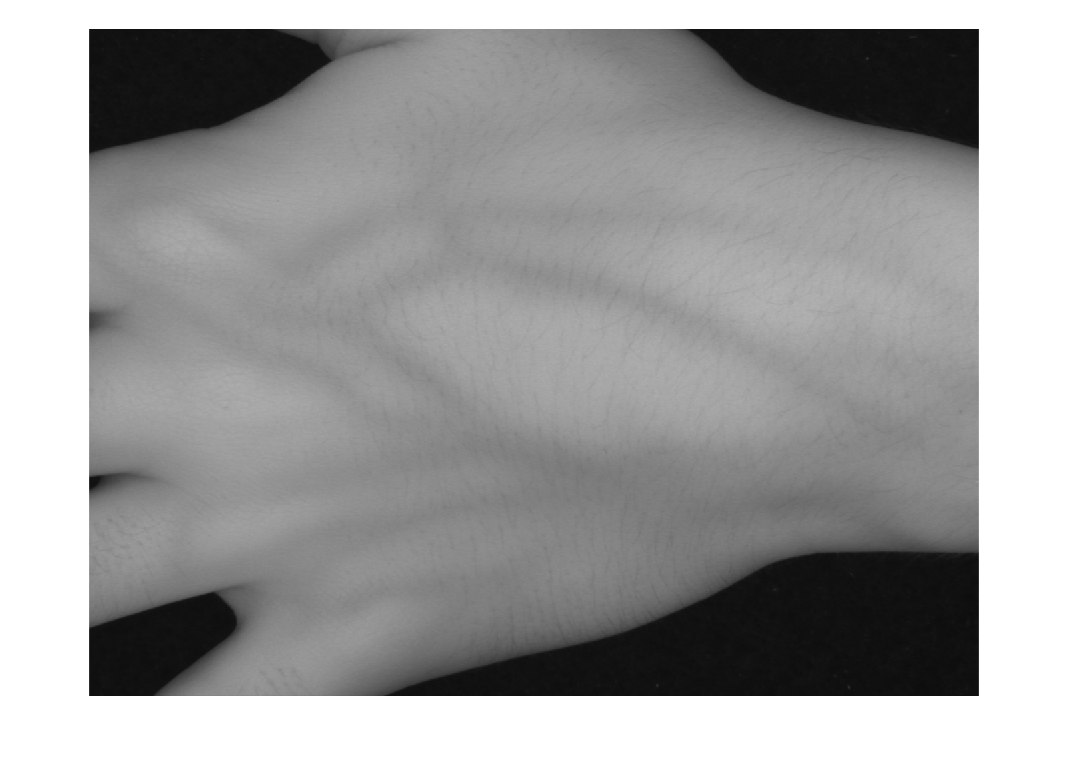

% clear; clc;

imagem = imread('..\Dataset\31\16_L_N_L_BH_5.tif');

montage({imagem})

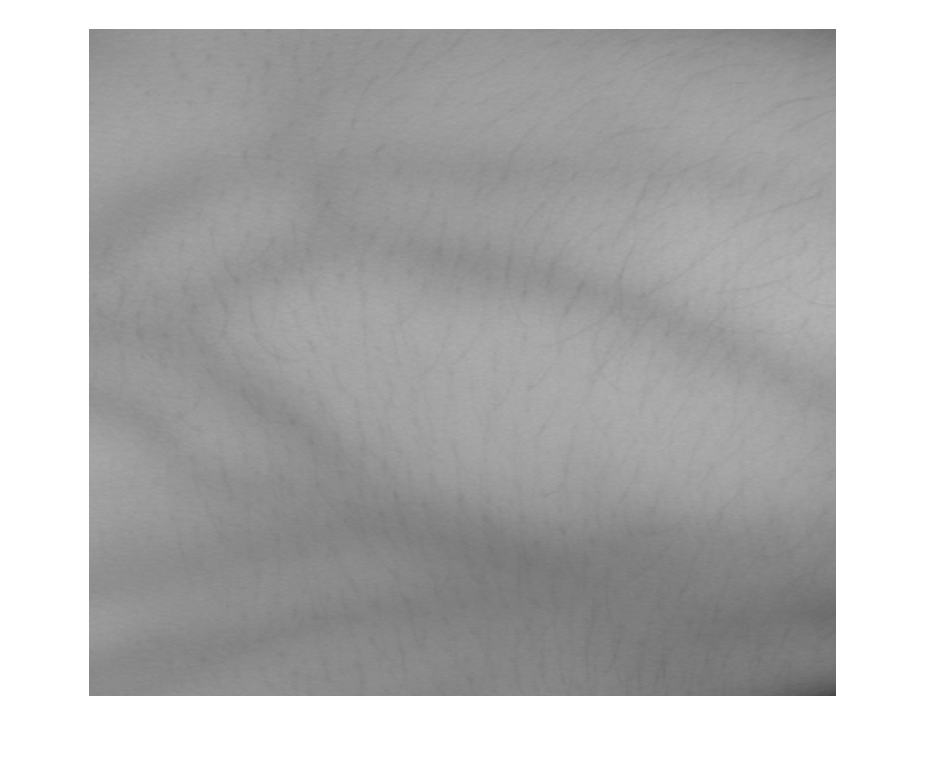

centroid = [360, 520];
d1 = 250;
d2 = 280;

E1 = (centroid(1) - d1):(centroid(1) + d1);
E2 = (centroid(2) - d2):(centroid(2) + d2);

% ROI = imagemCrop;
% ROI(E1, E2) = 0;
ROI = imagem(E1,E2);
% imshow(ROI)

montage({ROI})

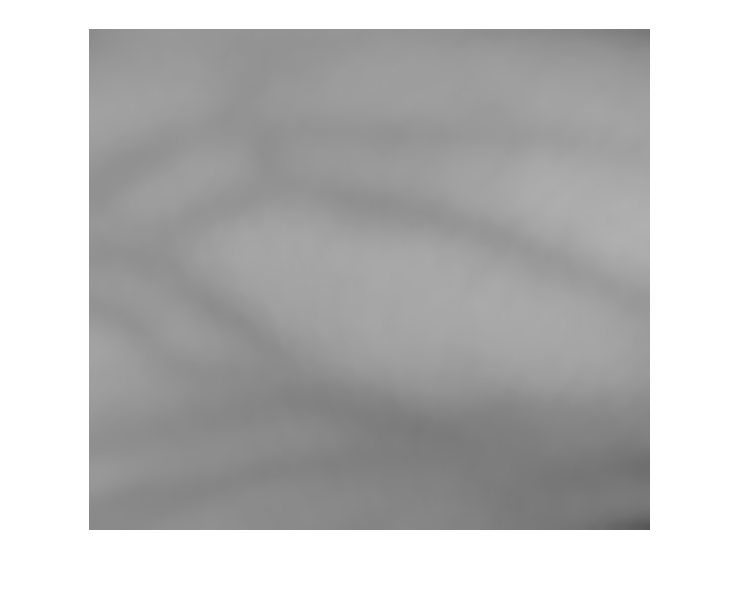

ROI = medfilt2(ROI, [16,16],'symmetric');
imshow(ROI)

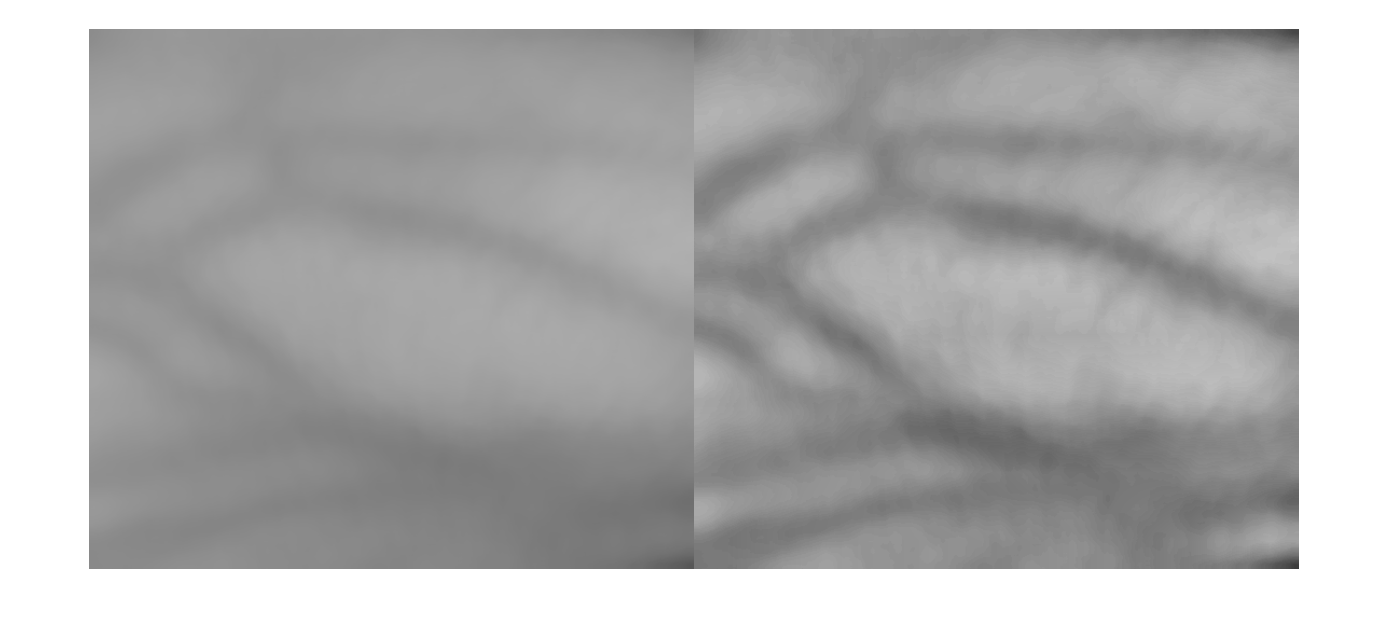

adaptHistEqual = adapthisteq(ROI);
montage({ROI, adaptHistEqual})

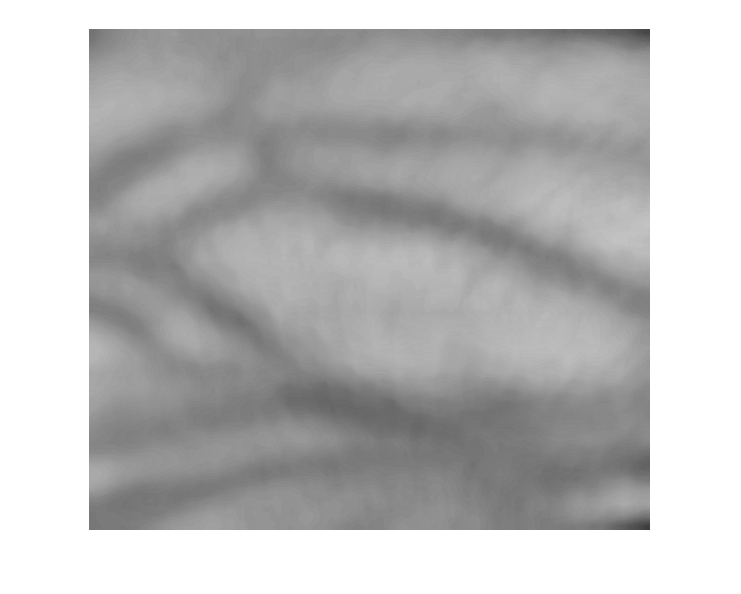

points = detectSURFFeatures(adaptHistEqual);
imshow(adaptHistEqual); hold on;

plot(points);

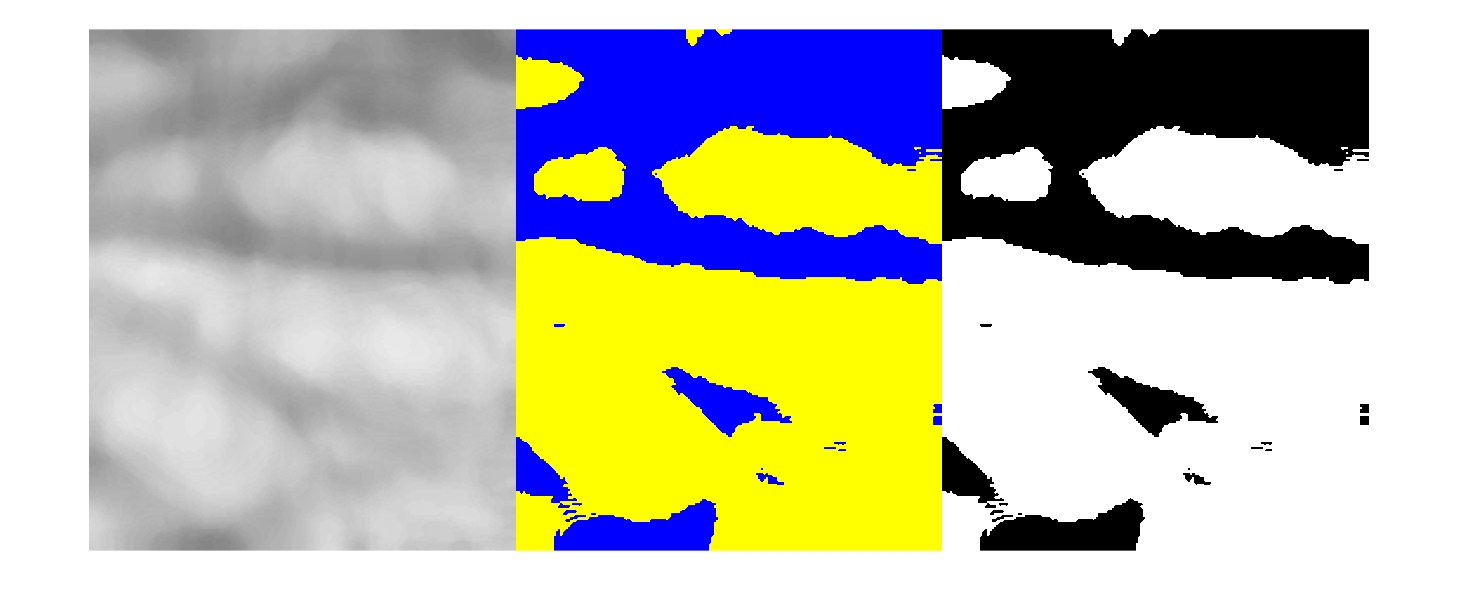

L = imsegkmeans(adaptHistEqual,2);
B = labeloverlay(adaptHistEqual,L);

img = imbinarize(B);
imgBinarize1 = img(:,:,1);
montage({adaptHistEqual, img, imgBinarize1}, 'Size', [1,3])

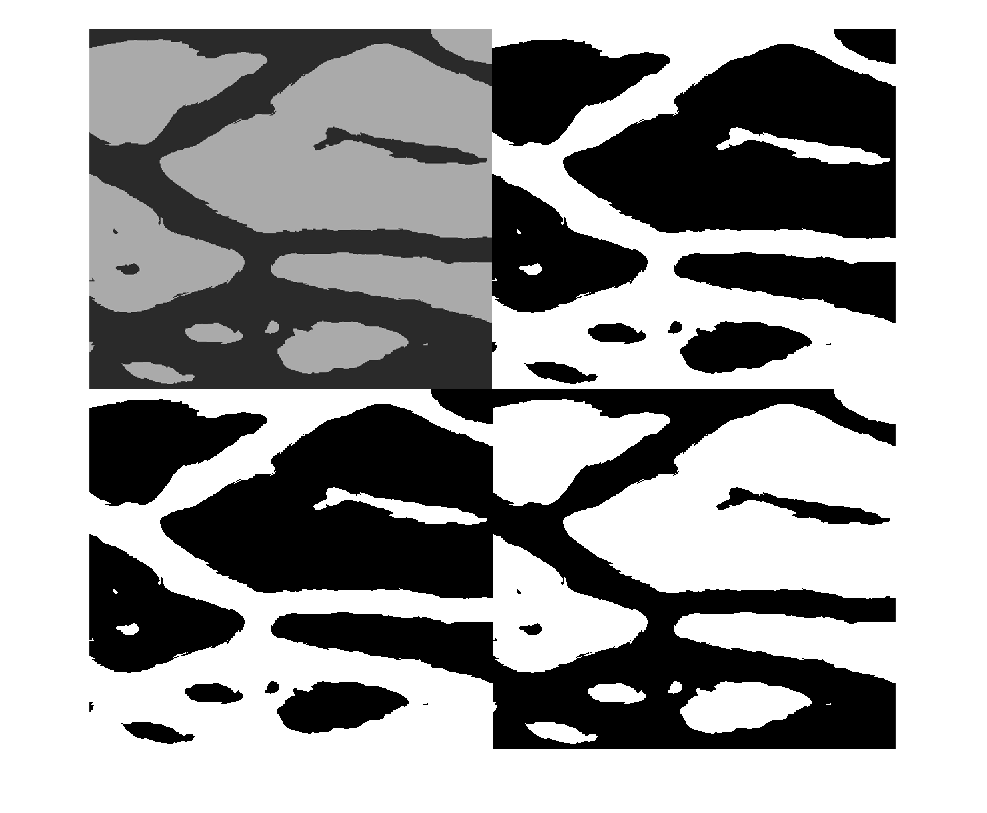

imgHsv = rgb2hsv(uint8(img*255));
imgLab = rgb2lab(uint8(img*255));
imgGray = rgb2gray(uint8(img*255));
imgYcbcr = rgb2ycbcr(uint8(img*255));

montage({imgHsv(:,:,1), imbinarize(imgLab(:,:,3)), imbinarize(imgGray), imbinarize(imgYcbcr(:,:,2))}, 'Size', [2,2])

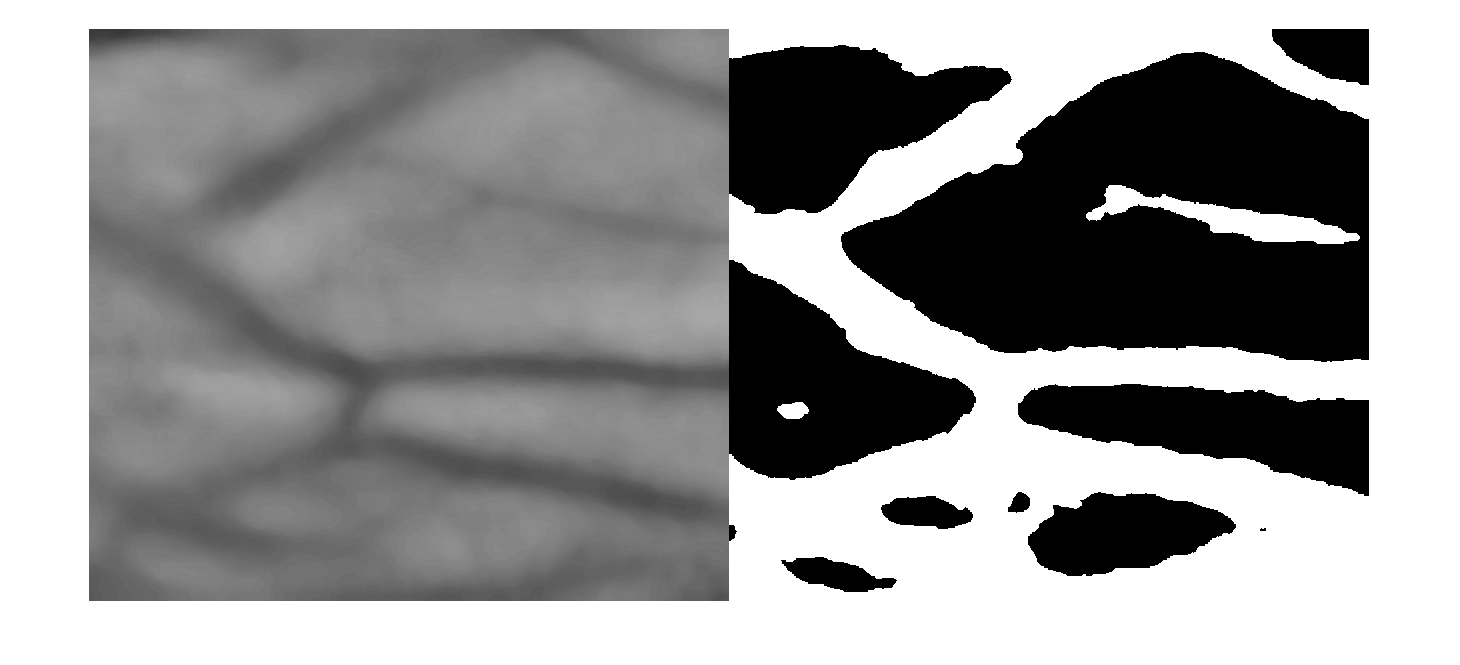

se2 = strel('disk',4);

imgErode2 = imerode(~imbinarize(imgYcbcr(:,:,2)),se2);
imgEroDil = imdilate(imgErode2, se2);

montage({adaptHistEqual, imgEroDil}, 'Size', [1,2])